clc;
clear all;
close all;
load('prob4_data.mat'); % Load the data

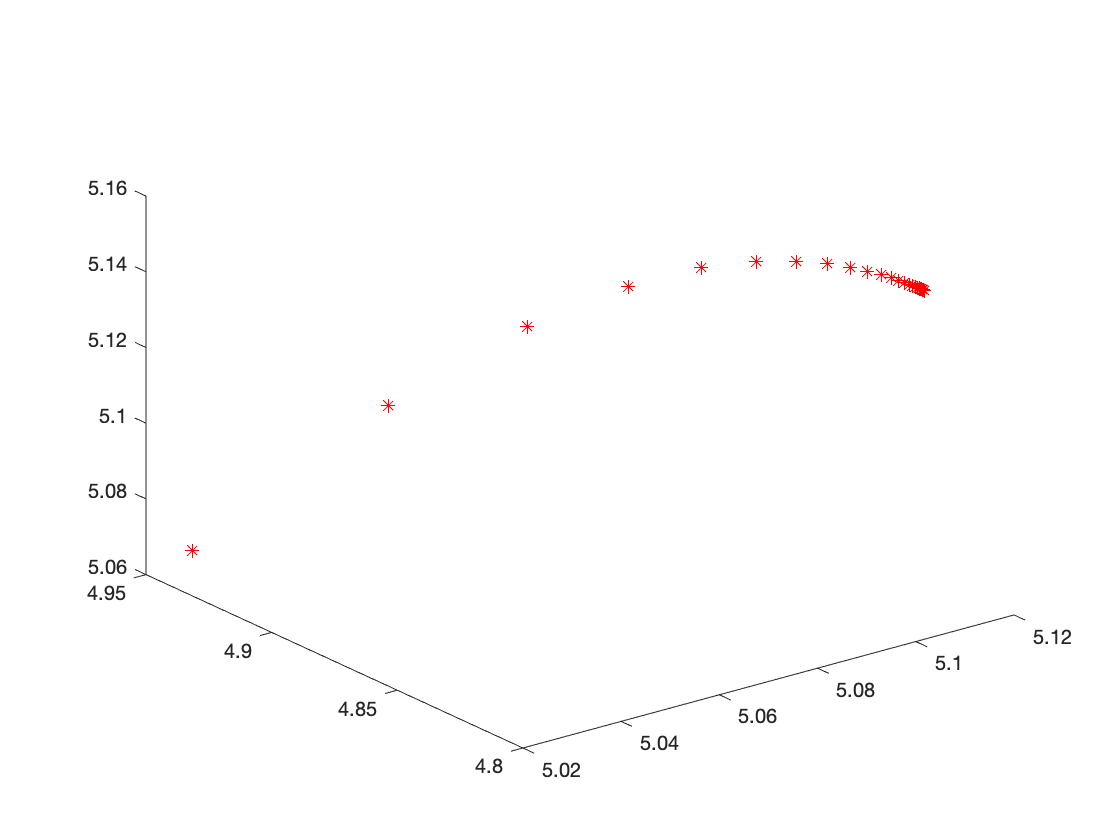

% Given 4 Matrices used in calculation of Projection Matrix
A = C(1:2,1:3,:);
b = C(1:2,4,:);
c = C(3,1:3,:);
d = C(3,4,:);


R1 = diag(R(1:2,1:2));
R2 = diag(R(3:4,3:4));
R3 = diag(R(5:6,5:6));
R4 = diag(R(7:8,7:8));

R_ = 0*ones(2,1,4);
R_(:,:,1) = R1;
R_(:,:,2) = R2;
R_(:,:,3) = R3;
R_(:,:,4) = R4;

% Initial value of x
x = [5 5 5]';
% Initial value of dX
dX = [1 1 1]';

eps = 1e-6;

while norm(dX) > eps
    
    Z_bar = zeros(2,4);
    for i = 1:4
        Z_bar(:,i) = ((A(:,:,i)*x + b(:,:,i))/(c(:,:,i)*x + d(:,:,i))); % 
    end
    Zbar = reshape(Z_bar,[8,1]); % reshape 8x1 matrix
    dZ = Z - Zbar;
    
    H = zeros(2,3,4);
    for j = 1:4
        H(:,:,j) = (A(:,:,j) * d(:,:,j) - b(:,:,j) * c(:,:,j))/(c(:,:,j)*x + d(:,:,j))^2;
    end
    H_bar = [H(:,:,1);H(:,:,2);H(:,:,3);H(:,:,4)]; % reshape the H - 8x3 matrix
    % 3x3 matrix
    P = inv(H_bar' * inv(R) * H_bar);
    % 3x8 matrix
    K = P * H_bar' * inv(R);
    
    dX = K * dZ;
    x = x + dX;
    % Plotting 
    plot3(x(1),x(2),x(3), 'r*'); hold on
end
hold off

% Optimal estimate
disp("Optimal Estimate")

Optimal Estimate


disp(x)

   5.113223042328524
   4.822400631738211
   5.141330039101297



% Error covariance matrix
disp("Error Covariance Matrix")

Error Covariance Matrix


disp(P)

   0.212333916183521   0.014584219435942   0.009678364378415
   0.014584219435942   0.054038331622322  -0.001930982854826
   0.009678364378415  -0.001930982854826   0.036510406894629



% Part (b)
disp("Semi-major axis of Gaussian Density Ellipsoid")

Semi-major axis of Gaussian Density Ellipsoid


disp("The direction that the estimate is most uncertain is the ")

The direction that the estimate is most uncertain is the 


% Calculate the eigenvalues and eigenvectors
[eigenvec, eigenval] = eig(P);

% Get the index of the largest eigenvector
[large_row, large_col] = find(eigenval== max(max(eigenval)));

largestEigenVec = eigenvec(:, large_row);

% The largest Eigenvalue
largestEigenVal = max(max(eigenval));

% Part (c)
disp("Semi-minor axis of Gaussian Density Ellipsoid")

Semi-minor axis of Gaussian Density Ellipsoid


disp("The direction that the estimate is least uncertain is the ")

The direction that the estimate is least uncertain is the 



% Get the index of the smallest eigenvector
[small_row, small_col] = find(eigenval == min(max(eigenval)));

smallestEigenVec = eigenvec(:, small_row);

% Smallest Eigenvalue
smallestEigenVal = min(max(eigenval));

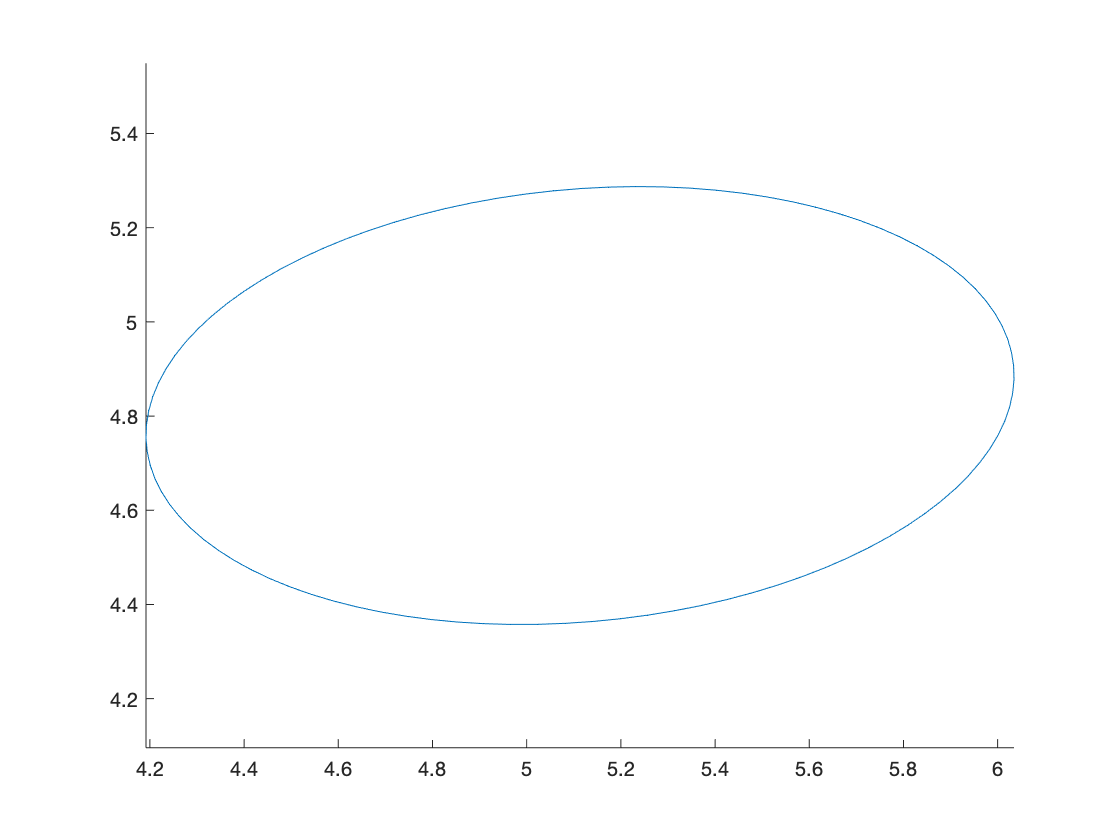

% Part (d)
% 86% Gaussian ellipsoid for the last two components of x.
figure
plot_gaussian_ellipsoid(x(1:2),P(1:2,1:2),2);
axis equal;

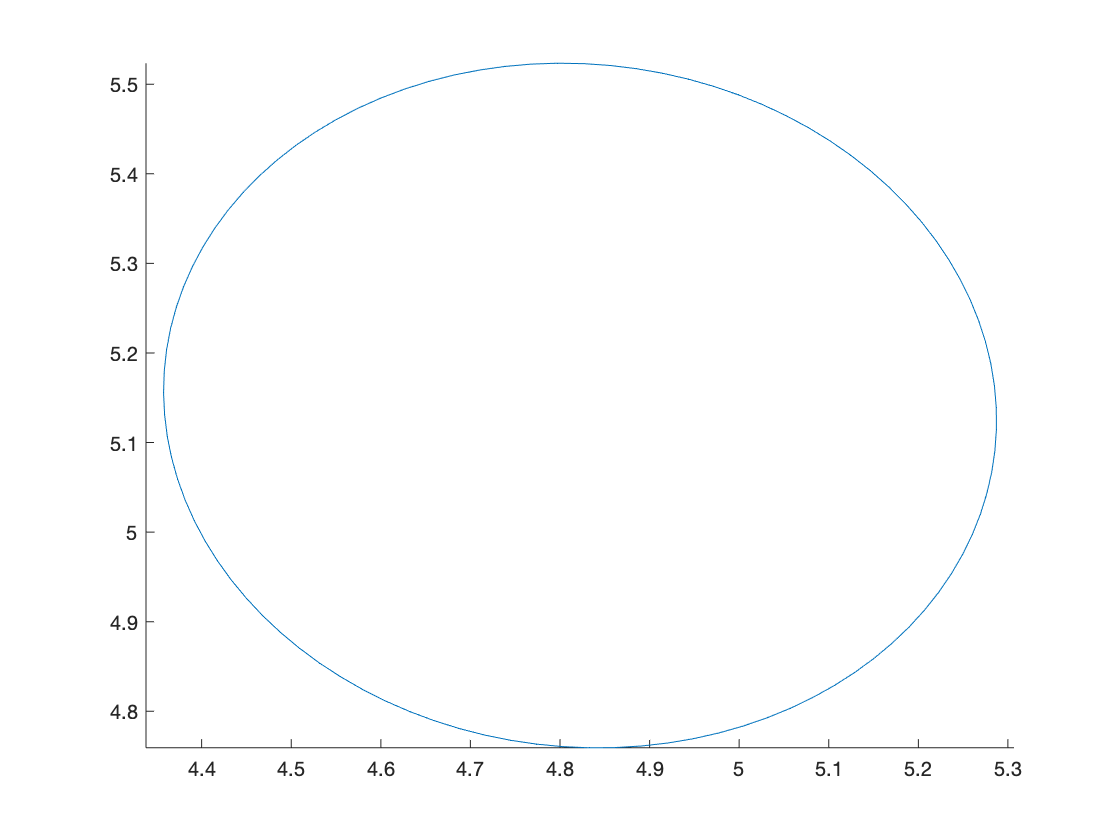

% Part(e) - 
% 86% Gaussian ellipsoid for the last two components of x.
figure
plot_gaussian_ellipsoid(x(2:3),P(2:3,2:3),2);
axis equal